%Fuselage Parameters
Df=15.08; %ft
LNose = 13.33; %ft
LMid = 44; %ft
LTail = 37.3 %ft

LTail = 37.3000

DBase = 1.5 %ft

DBase = 1.5000

UpsweepAngle = atan((Df/2-DBase/2)/LTail); %rad

%Planform Parameters
S = 1561; %ft^2
AR = 8.75

AR = 8.7500

AR2 = 5.23

AR2 = 5.2300

b2=100

b2 = 100

TaperRatio = 0.6;
b = sqrt(AR*S)

b = 116.8707

Q = 1.01

Q = 1.0100

SweepQuartC = 0;
e = 0.9;
K = 1/(e*pi*AR)

K = 0.0404


%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 151433*0.946

W = 1.4326e+05


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000

CLDMin = 0.1

CLDMin = 0.1000



% Df = 0:0.5:20

Df =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000


LMid = 0:1:100

for x=1:41
    
    [CDo_fuse] = ParaDragFuse(h,V,LMid(x),LNose,LTail,Df,DynVisc,S)%Alt(ft), velocity(kts), CharLength(ft), Dia(ft), Dynamic Visc(Slug/ft-s), Reference Area(ft^2)
    
    [CDo_wing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,SweepQuartC,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax)
    
    CDo_total(x)= CDo_fuse + CDo_wing
    
end

FF = Inf

CDo_fuse = NaN

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.6958

Sexp = 1561

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.2079e+03

CDo = 0.0074

CDo_wing = 0.0074

CDo_total = NaN

FF = 1.4732

CDo_fuse = 2.2925e-04

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.6672

Sexp = 1.5527e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.1907e+03

CDo = 0.0073

CDo_wing = 0.0073

CDo_total =        NaN    0.0076


FF = 1.2366

CDo_fuse = 3.8489e-04

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.6387

Sexp = 1.5443e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.1736e+03

CDo = 0.0073

CDo_wing = 0.0073

CDo_total =        NaN    0.0076    0.0077


FF = 1.1580

CDo_fuse = 5.4060e-04

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.6101

Sexp = 1.5360e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.1565e+03

CDo = 0.0073

CDo_wing = 0.0073

CDo_total =        NaN    0.0076    0.0077    0.0078


FF = 1.1189

CDo_fuse = 6.9646e-04

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.5815

Sexp = 1.5277e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.1395e+03

CDo = 0.0072

CDo_wing = 0.0072

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079


FF = 1.0957

CDo_fuse = 8.5259e-04

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.5530

Sexp = 1.5194e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.1224e+03

CDo = 0.0072

CDo_wing = 0.0072

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080


FF = 1.0808

CDo_fuse = 0.0010

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.5244

Sexp = 1.5112e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.1055e+03

CDo = 0.0071

CDo_wing = 0.0071

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081


FF = 1.0706

CDo_fuse = 0.0012

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.4958

Sexp = 1.5029e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.0885e+03

CDo = 0.0071

CDo_wing = 0.0071

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083


FF = 1.0637

CDo_fuse = 0.0013

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.4672

Sexp = 1.4947e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.0716e+03

CDo = 0.0071

CDo_wing = 0.0071

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084


FF = 1.0590

CDo_fuse = 0.0015

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.4387

Sexp = 1.4864e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.0546e+03

CDo = 0.0070

CDo_wing = 0.0070

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085


FF = 1.0562

CDo_fuse = 0.0016

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.4101

Sexp = 1.4782e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.0378e+03

CDo = 0.0070

CDo_wing = 0.0070

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086


FF = 1.0548

CDo_fuse = 0.0018

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.3815

Sexp = 1.4700e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.0209e+03

CDo = 0.0069

CDo_wing = 0.0069

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088


FF = 1.0547

CDo_fuse = 0.0020

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.3530

Sexp = 1.4619e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 3.0041e+03

CDo = 0.0069

CDo_wing = 0.0069

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089


FF = 1.0558

CDo_fuse = 0.0021

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.3244

Sexp = 1.4537e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.9873e+03

CDo = 0.0069

CDo_wing = 0.0069

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090


FF = 1.0581

CDo_fuse = 0.0023

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.2958

Sexp = 1.4455e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.9706e+03

CDo = 0.0068

CDo_wing = 0.0068

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091


FF = 1.0614

CDo_fuse = 0.0025

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.2672

Sexp = 1.4374e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.9538e+03

CDo = 0.0068

CDo_wing = 0.0068

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093


FF = 1.0658

CDo_fuse = 0.0027

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.2387

Sexp = 1.4293e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.9371e+03

CDo = 0.0068

CDo_wing = 0.0068

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094


FF = 1.0713

CDo_fuse = 0.0028

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.2101

Sexp = 1.4211e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.9205e+03

CDo = 0.0067

CDo_wing = 0.0067

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095


FF = 1.0779

CDo_fuse = 0.0030

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.1815

Sexp = 1.4131e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.9038e+03

CDo = 0.0067

CDo_wing = 0.0067

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097


FF = 1.0856

CDo_fuse = 0.0032

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.1530

Sexp = 1.4050e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.8872e+03

CDo = 0.0066

CDo_wing = 0.0066

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098


FF = 1.0945

CDo_fuse = 0.0034

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.1244

Sexp = 1.3969e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.8706e+03

CDo = 0.0066

CDo_wing = 0.0066

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100


FF = 1.1045

CDo_fuse = 0.0036

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.0958

Sexp = 1.3888e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.8541e+03

CDo = 0.0066

CDo_wing = 0.0066

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102


FF = 1.1157

CDo_fuse = 0.0038

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.0672

Sexp = 1.3808e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.8376e+03

CDo = 0.0065

CDo_wing = 0.0065

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103


FF = 1.1283

CDo_fuse = 0.0040

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.0387

Sexp = 1.3728e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.8211e+03

CDo = 0.0065

CDo_wing = 0.0065

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105


FF = 1.1421

CDo_fuse = 0.0043

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 16.0101

Sexp = 1.3648e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.8046e+03

CDo = 0.0064

CDo_wing = 0.0064

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107


FF = 1.1572

CDo_fuse = 0.0045

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.9815

Sexp = 1.3568e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.7882e+03

CDo = 0.0064

CDo_wing = 0.0064

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109


FF = 1.1738

CDo_fuse = 0.0047

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.9530

Sexp = 1.3488e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.7717e+03

CDo = 0.0064

CDo_wing = 0.0064

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111


FF = 1.1917

CDo_fuse = 0.0050

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.9244

Sexp = 1.3408e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.7554e+03

CDo = 0.0063

CDo_wing = 0.0063

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113


FF = 1.2112

CDo_fuse = 0.0053

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.8958

Sexp = 1.3329e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.7390e+03

CDo = 0.0063

CDo_wing = 0.0063

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116


FF = 1.2322

CDo_fuse = 0.0056

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.8672

Sexp = 1.3249e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.7227e+03

CDo = 0.0063

CDo_wing = 0.0063

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118


FF = 1.2547

CDo_fuse = 0.0059

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.8387

Sexp = 1.3170e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.7064e+03

CDo = 0.0062

CDo_wing = 0.0062

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118    0.0121


FF = 1.2789

CDo_fuse = 0.0062

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.8101

Sexp = 1.3091e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.6902e+03

CDo = 0.0062

CDo_wing = 0.0062

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118    0.0121    0.0124


FF = 1.3048

CDo_fuse = 0.0065

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.7815

Sexp = 1.3012e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.6739e+03

CDo = 0.0061

CDo_wing = 0.0061

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118    0.0121    0.0124    0.0126


FF = 1.3324

CDo_fuse = 0.0068

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.7530

Sexp = 1.2933e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.6577e+03

CDo = 0.0061

CDo_wing = 0.0061

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118    0.0121    0.0124    0.0126    0.0130


FF = 1.3618

CDo_fuse = 0.0072

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.7244

Sexp = 1.2854e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.6416e+03

CDo = 0.0061

CDo_wing = 0.0061

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118    0.0121    0.0124    0.0126    0.0130    0.0133


FF = 1.3930

CDo_fuse = 0.0076

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.6958

Sexp = 1.2776e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.6254e+03

CDo = 0.0060

CDo_wing = 0.0060

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118    0.0121    0.0124    0.0126    0.0130    0.0133    0.0136


FF = 1.4261

CDo_fuse = 0.0080

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.6672

Sexp = 1.2697e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.6093e+03

CDo = 0.0060

CDo_wing = 0.0060

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118    0.0121    0.0124    0.0126    0.0130    0.0133    0.0136    0.0140


FF = 1.4611

CDo_fuse = 0.0084

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.6387

Sexp = 1.2619e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.5932e+03

CDo = 0.0060

CDo_wing = 0.0060

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118    0.0121    0.0124    0.0126    0.0130    0.0133    0.0136    0.0140    0.0144


FF = 1.4981

CDo_fuse = 0.0089

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.6101

Sexp = 1.2541e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.5772e+03

CDo = 0.0059

CDo_wing = 0.0059

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118    0.0121    0.0124    0.0126    0.0130    0.0133    0.0136    0.0140    0.0144    0.0148


FF = 1.5371

CDo_fuse = 0.0093

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.5815

Sexp = 1.2463e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.5611e+03

CDo = 0.0059

CDo_wing = 0.0059

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118    0.0121    0.0124    0.0126    0.0130    0.0133    0.0136    0.0140    0.0144    0.0148    0.0152


FF = 1.5783

CDo_fuse = 0.0098

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.5530

Sexp = 1.2385e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.5451e+03

CDo = 0.0059

CDo_wing = 0.0059

CDo_total =        NaN    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0088    0.0089    0.0090    0.0091    0.0093    0.0094    0.0095    0.0097    0.0098    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0111    0.0113    0.0116    0.0118    0.0121    0.0124    0.0126    0.0130    0.0133    0.0136    0.0140    0.0144    0.0148    0.0152    0.0157


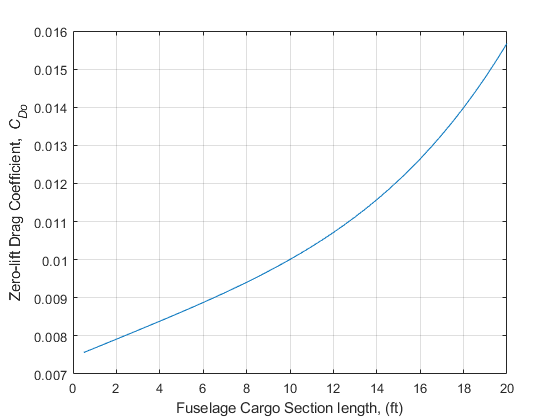


plot (LMid,CDo_total)
xlabel('Fuselage Cargo Section length, (ft)')
ylabel('Zero-lift Drag Coefficient, {\it C_{Do}}')
grid on